clear;
clc;
close all;

% Locate to the current file location
tmp = matlab.desktop.editor.getActive;
cd(fileparts(tmp.Filename));

addpath(genpath('.'));

% Load the data from the specified file
load data/example_letter/R.mat;
data = demos;

% Data Initialization
[orig_data, out_data_temp] = f_UTFMP_data_deal(data);

% 1. UTFMP_Seg_t - Unit Tangent Fuzzy Motion Primitives - With Trajectory Segmentation - Time Trajectory
whether_SubTeraj = true; whether_time = true;
Result_UTFMP_Seg_t = f_UTFMP(orig_data, whether_SubTeraj, whether_time);

The consumption time is: 0.70317 seconds



% 2. UTFMP_Seg_p - Unit Tangent Fuzzy Motion Primitives - With Trajectory Segmentation - Path Trajectory
whether_SubTeraj = true; whether_time = false;
Result_UTFMP_Seg_p = f_UTFMP(orig_data, whether_SubTeraj, whether_time);

The consumption time is: 0.57183 seconds



% 3. UTFMP_NoSeg_t - Unit Tangent Fuzzy Motion Primitives - Without Trajectory Segmentation - Time Trajectory
whether_SubTeraj = false; whether_time = true;
Result_UTFMP_NoSeg_t = f_UTFMP(orig_data, whether_SubTeraj, whether_time);

The consumption time is: 0.55687 seconds



% 4. UTFMP_NoSeg_p - Unit Tangent Fuzzy Motion Primitives - Without Trajectory Segmentation - Path Trajectory
whether_SubTeraj = false; whether_time = false;
Result_UTFMP_NoSeg_p = f_UTFMP(orig_data, whether_SubTeraj, whether_time);

The consumption time is: 0.55531 seconds


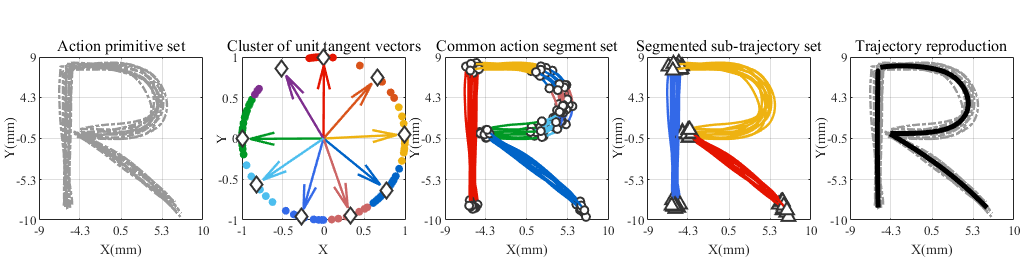

历时 2.262019 秒。



% Plotting results
figure(1); clf;
d_UTFMP_paper_plot(Result_UTFMP_Seg_t);

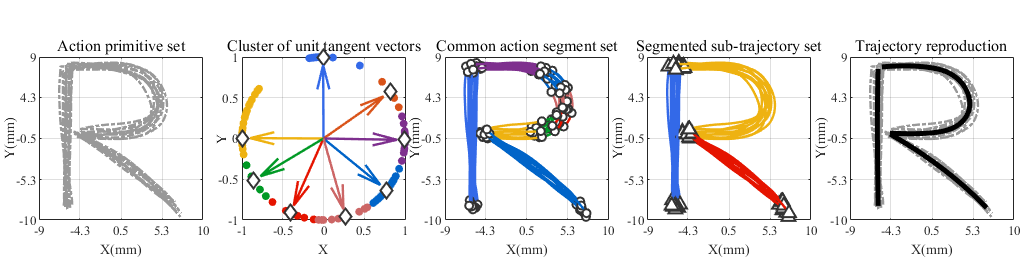

历时 2.113718 秒。



figure(2); clf;
d_UTFMP_paper_plot(Result_UTFMP_Seg_p);

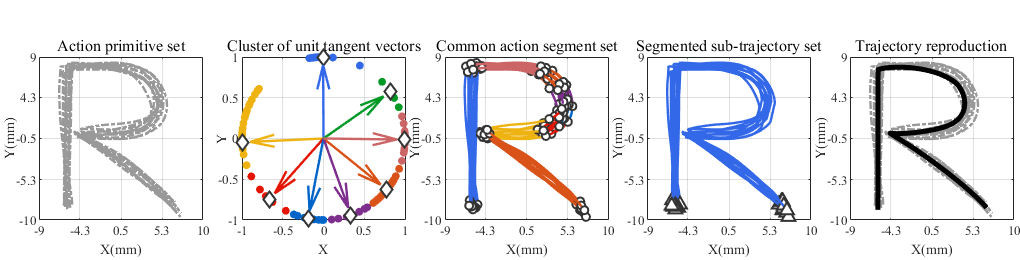

历时 2.144655 秒。



figure(3); clf;
d_UTFMP_paper_plot(Result_UTFMP_NoSeg_t);

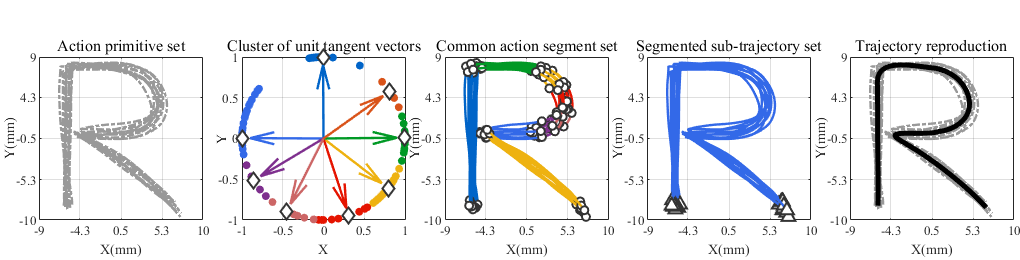

历时 2.060559 秒。



figure(4); clf;
d_UTFMP_paper_plot(Result_UTFMP_NoSeg_p);

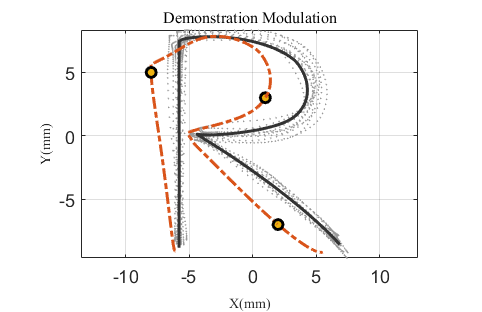

历时 0.098377 秒。



% Insert custom input data for further analysis
input_insert_data = [];
input_insert_data.pos = [];
input_insert_data.pos(1,:) = [-8,5,1];
input_insert_data.pos(2,:) = [1,3,1];
input_insert_data.pos(3,:) = [2,-7,1];
input_insert_data.vel = [];
input_insert_data.vel(1,:) = [0,0,0];
input_insert_data.vel(2,:) = [0,0,0];
input_insert_data.vel(3,:) = [0,0,0];
input_insert_data.input_index = [];
input_insert_data.input_index(1,:) = 0.2;
input_insert_data.input_index(2,:) = 0.5;
input_insert_data.input_index(3,:) = 0.9;

% Plot with custom input data
figure(21); clf;
d_UTFMP_paper_plot_2(Result_UTFMP_NoSeg_t, input_insert_data);

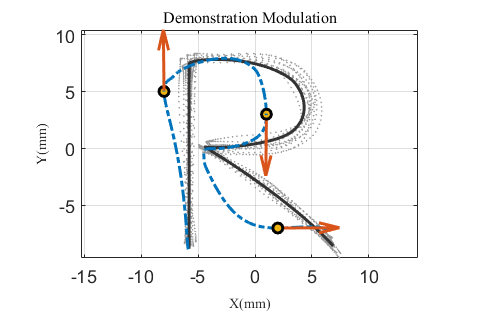

历时 0.099410 秒。



% Modify velocity for further analysis
input_insert_data = [];
input_insert_data.pos = [];
input_insert_data.pos(1,:) = [-8,5,1];
input_insert_data.pos(2,:) = [1,3,1];
input_insert_data.pos(3,:) = [2,-7,1];
input_insert_data.vel = [];
input_insert_data.vel(1,:) = [0,1,0];
input_insert_data.vel(2,:) = [0,-1,0];
input_insert_data.vel(3,:) = [1,0,0];
input_insert_data.input_index = [];
input_insert_data.input_index(1,:) = 0.2;
input_insert_data.input_index(2,:) = 0.5;
input_insert_data.input_index(3,:) = 0.9;

% Plot with modified velocity data
figure(21); clf;
d_UTFMP_paper_plot_3(Result_UTFMP_NoSeg_t, input_insert_data);